# **Generate C Code for the Compressed AI Model **

Now that we have successfully compressed a deep neural network for bearing fault diagnosis, we would like to generate C code to deploy to an embedded system.

## 1. Export the network to Simulink

Load the quantized network.

load("quantized_net.mat")

Export the network to Simulink as Layer Block is one way to generate C code for a neural network.

exportNetworkToSimulink(quantizedNet,"ModelName","quantizedNetSim","FrameBased",true);

## 2. Compile the network in Simulink using Embedded Coder

Once the network is exported to Simulink, you can click Update Model in COMPILE tab in DEBUG.

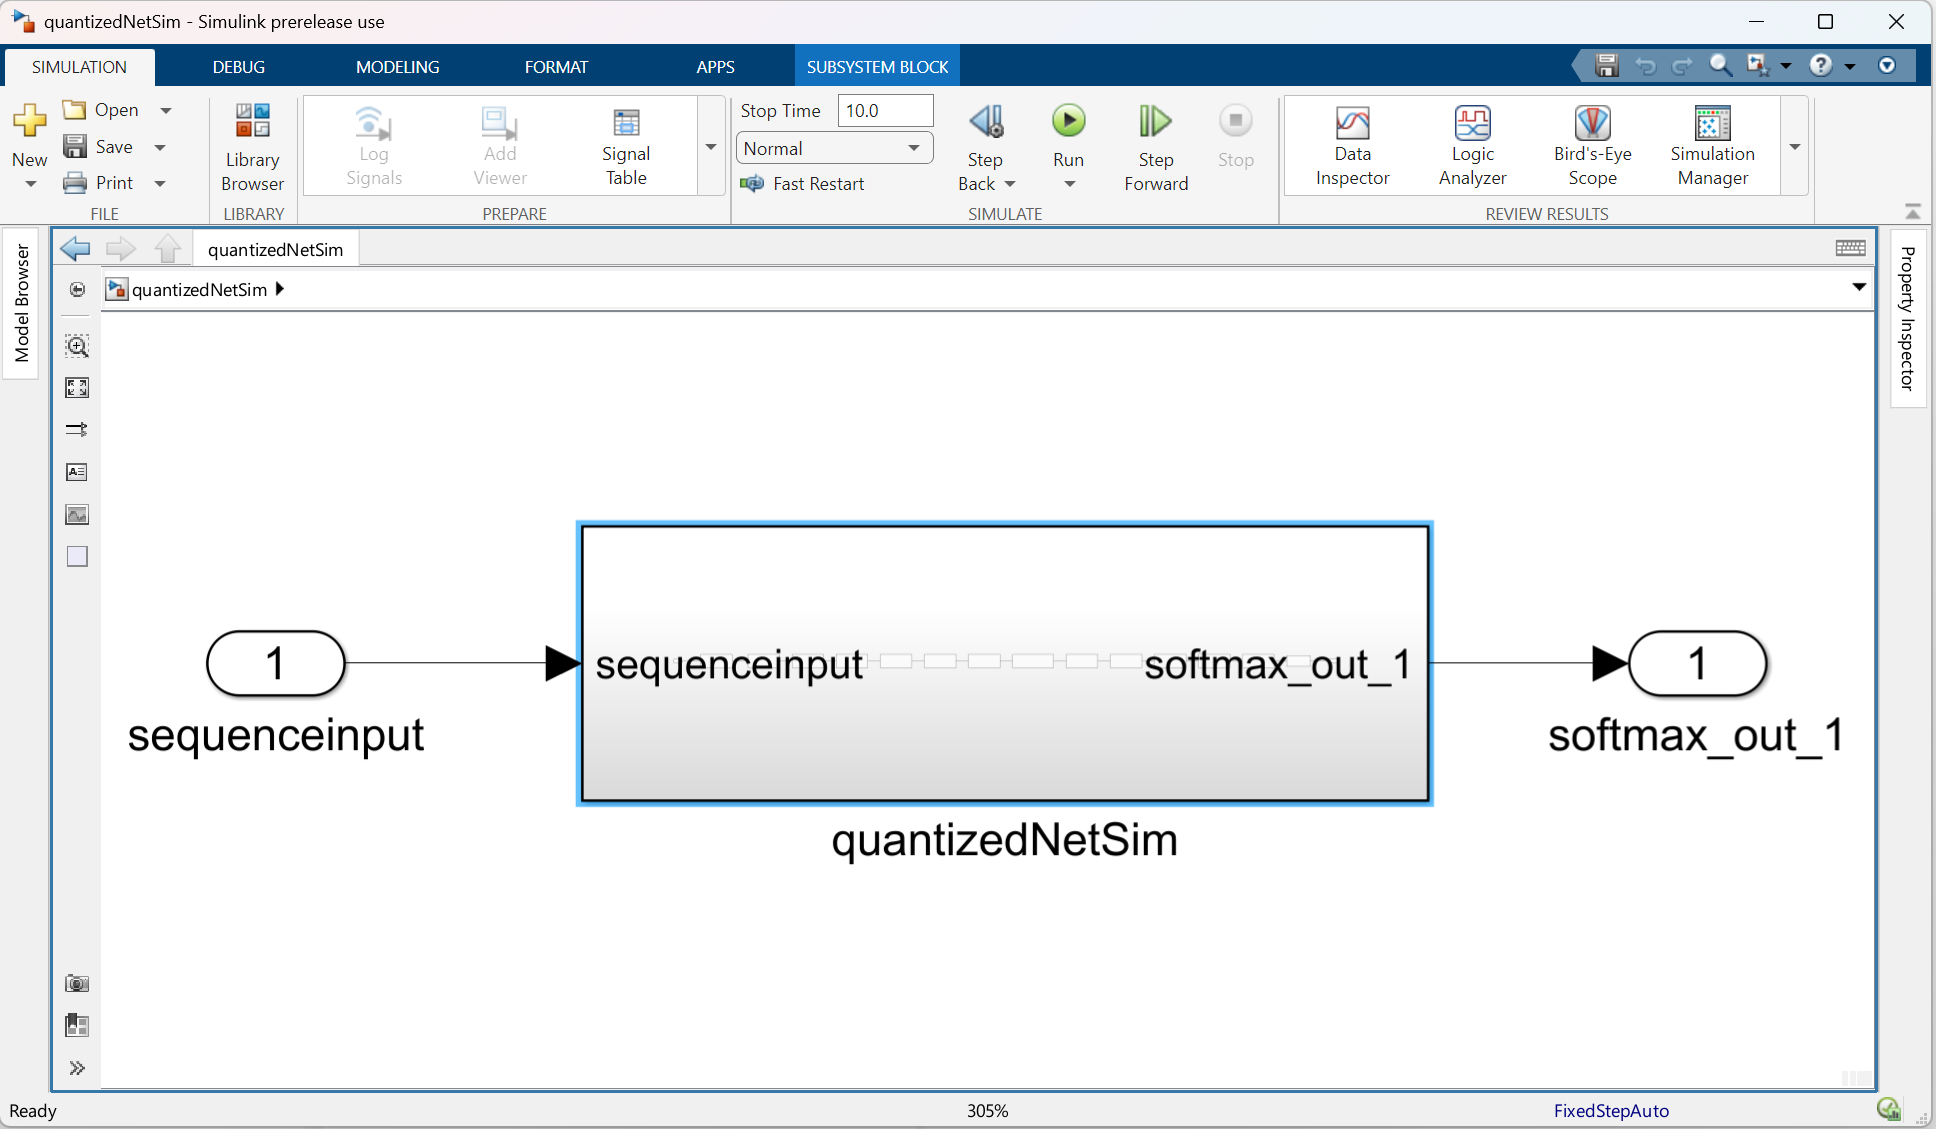

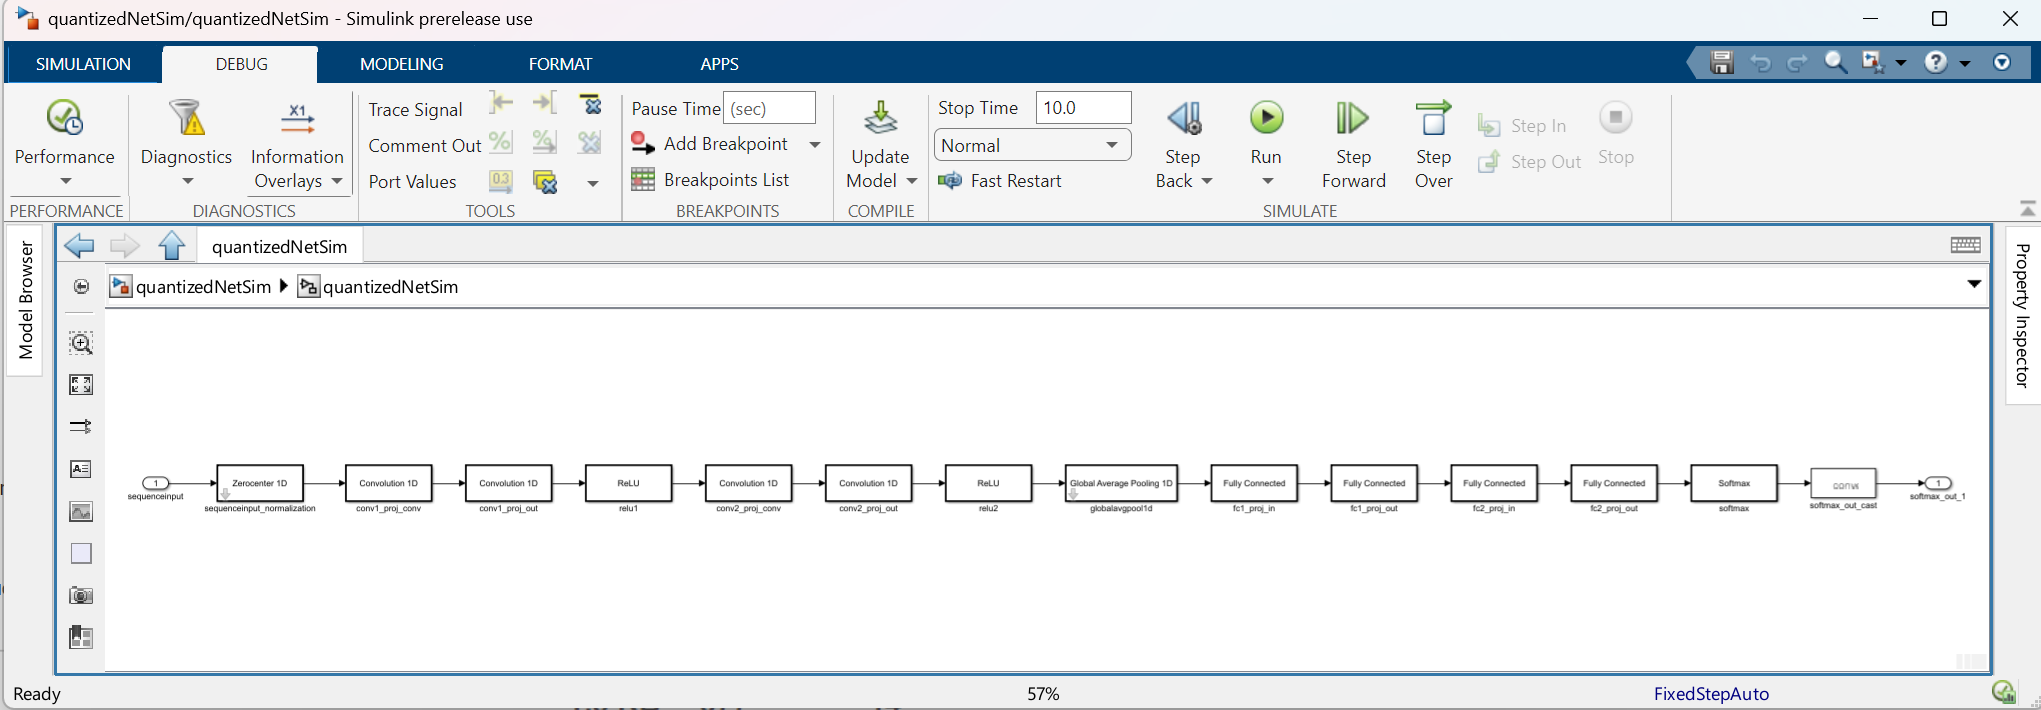

Open Embedded Coder from the APPS tab.

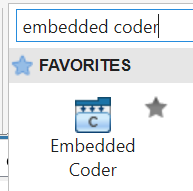

Click Quick Start and follow steps through to select options fit for your purpose. In this exercise, you can choose C code and Single instance in the Output section. Then choose ARM Compatible for Device Vendor and ARM Cortex-M for Device Type in the Word Size section. Choose Execution efficiency in Optimization. You will see some settings are changed due to this selection.

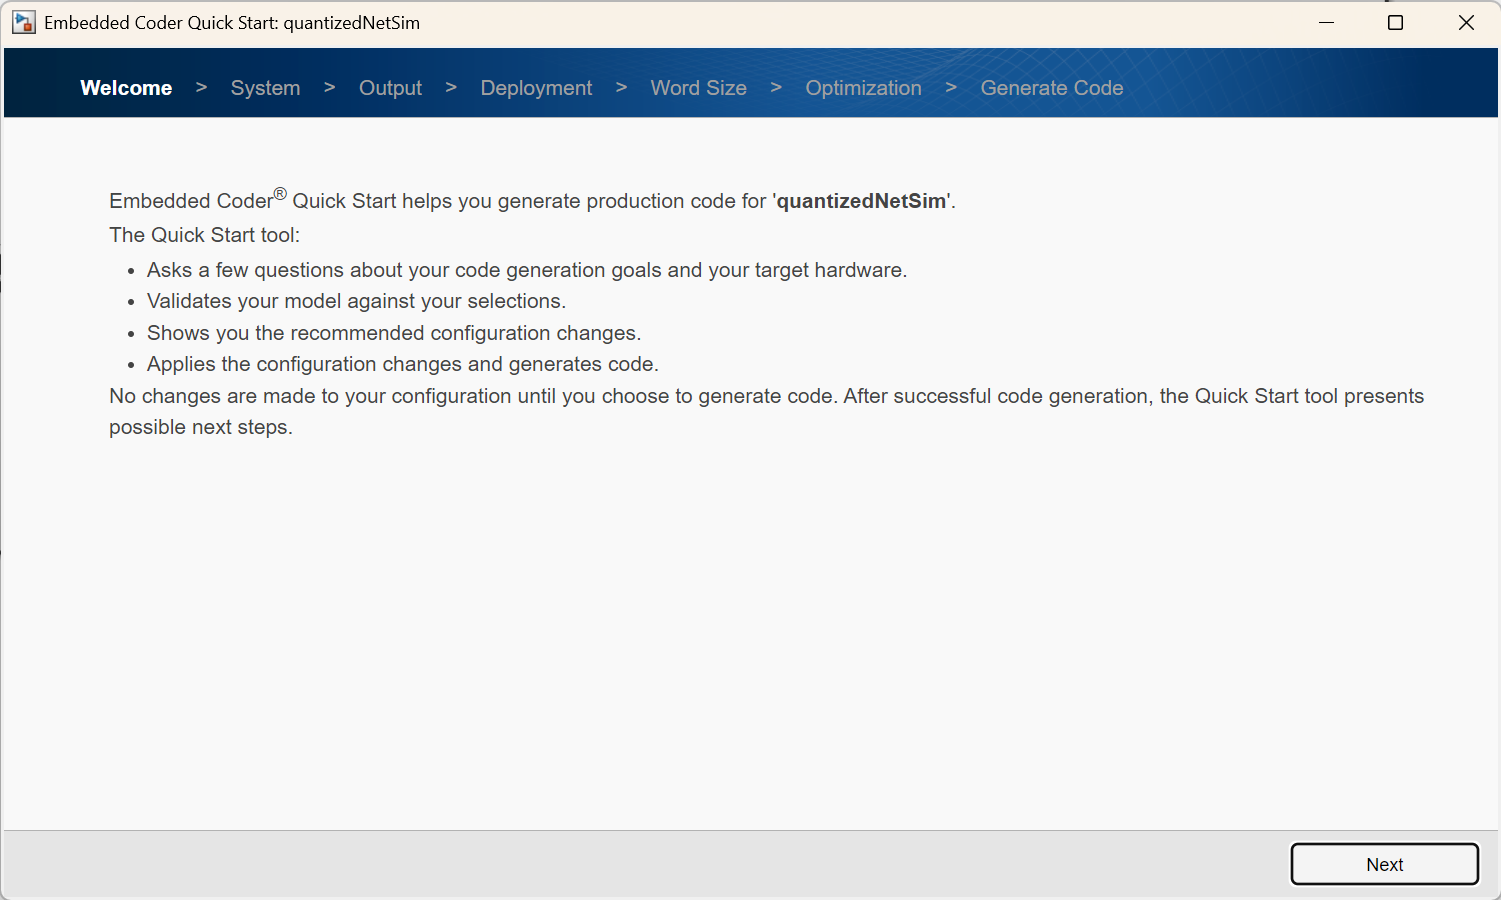

Click Build to generate code.

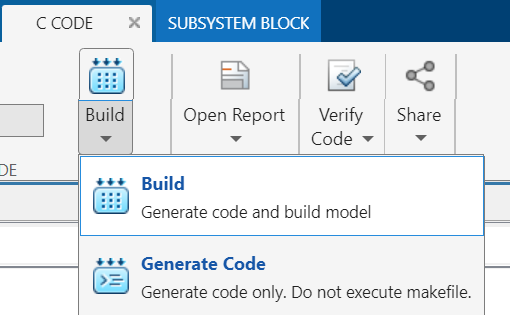

Once the code generation finished, you can click on Open Report to check the generated code.

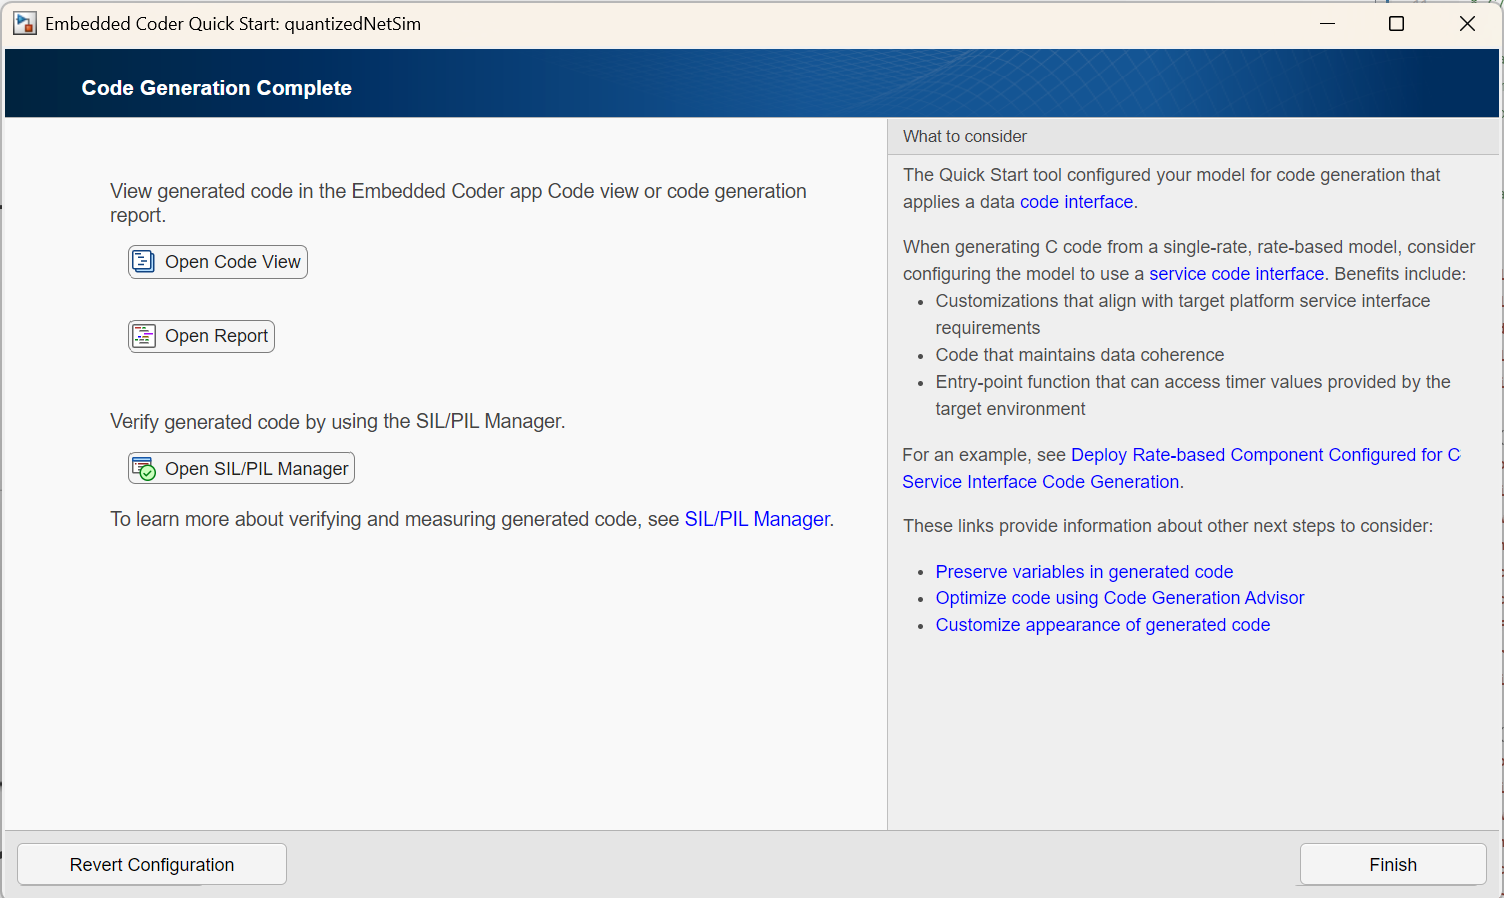

You can find the generated C files and H files. The model weights, forward path are easy to find in the files.